# Seminarski zadatak

### Opis zadatka

Na slici je prikazan rotacijski hidraulički sustav, koji se sastoji od hidrauličkog motora upravljanog proporcionalnim ventilom, pri čemu se upravlja kutem zakreta tereta.

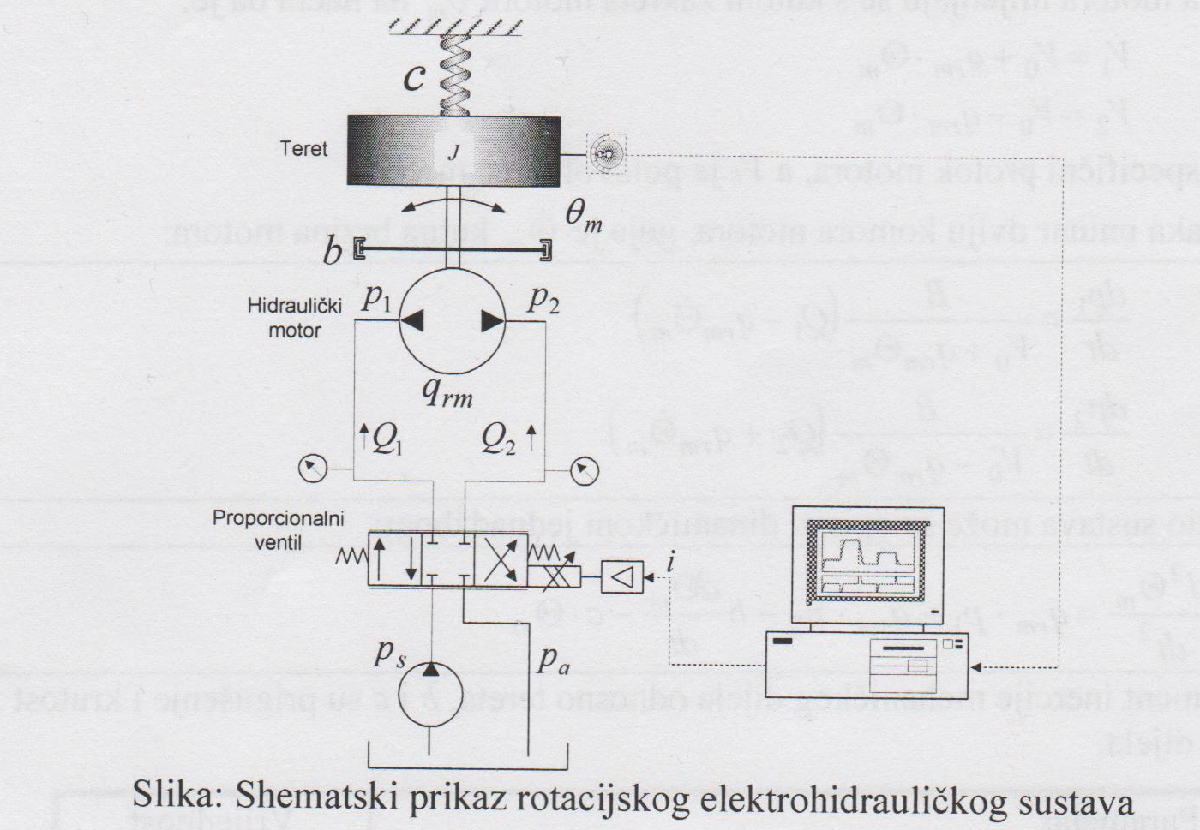

Dinamika proporcionalnog ventila može se opisati prijenosnom funkcijom P1 člana:


$$\frac{y_v(s)}{i(s)} = \frac{K_v}{\frac{1}{\omega_v}+1}$$


$y_v$ - pozicija klipa proporcionalnog ventila, m

$i$ - ulazna struja proporcionalnog ventila, A

$K_v$ - koeficijent pojačanja proporcionalnog ventila, m/A

$\omega_v$ - vlastita frekvencija proporcionalnog centila, rad/s

Jednadžbe protoka kroz proporcionalni ventil iznose:


$$Q_1(y_v,p_1)=\begin{cases}
y_v*\sqrt{|p_s-p_1|}*sign(p_s-p_1), & \text{za } y_v\geq0\\
y_v*\sqrt{|p_1-p_s|}*sign(p_1-p_s), & \text{za } y_v<0
\end{cases}$$



$$Q_2(y_v,p_2)=\begin{cases}
y_v*\sqrt{|p_2-p_a|}*sign(p_2-p_a), & \text{za } y_v\geq0\\
y_v*\sqrt{|p_s-p_s2}*sign(p_s-p_2), & \text{za } y_v<0
\end{cases}$$


$p_1$ - tlak u lijevoj komori motora

$p_2$ - tlak u desnoj komori motora

$p_s$ - tlak napajanja

$p_a$ - tlak spremnika

Pretpostavlja se da su tlakovi napajanja i spremnika konstantne veličine

Protoci $Q_1$ i $Q_2$ su:


$$Q_1(y_v,p_1)=-Q_2(y_v,p_2)$$


Za motor vrijedi slijedeća hidrodinamička jednadžba:


$$\frac{V}{B}*\frac{dp}{dt}+\frac{dV}{dt}=Q$$


$B$ - modul stišljivosti ulja

$V$- volumen motora

$p$ - tlak motora

$Q$ - protok motora

$ \theta_m$ - kut zakreta motora

Volumeni dviju komora motora mijenjaju se s kutom zakreta motora $ \theta_m$:


$$V_1=V_0+q_{rm}*\dot{\theta_m}$$



$$V_2=V_0-q_{rm}*\dot{\theta_m}$$


$q_{rm}$ - specifični protok motora

$V_0$ - poluvolumen motora

$\dot{\theta_m}$ - kutna brzina motora

Ponašanje tlaka unutar dviju komora motora:


$$\frac{dp_1}{dt}=\frac{B}{V_0+q_{rm}\theta_m}(Q1-q_{rm}\dot{\theta_m})$$



$$\frac{dp_2}{dt}=\frac{B}{V_0-q_{rm}\theta_m}(Q1+q_{rm}\dot{\theta_m})$$


Mehanički dio sustava može se opisati dinamičkom jednadžbom:


$$J*\frac{d^2\theta_m}{dt^2}=q_{rm}*p_1-q_{rm}*p_2-b\frac{d\theta_m}{dt}-c*\theta_m$$


$J$ - moment inercije mehaničkog dijela (tereta)

$b
$ - prigušenja mehaničkog dijela

$c$ - krutost mehaničkoh dijela

### Parametri sustava

global Kv omegav ps pa B V0 qrm J b c Km Kr
Kv = 5.55e-7;   % Koeficijent pojačanja proporcionalnog ventila 
omegav = 113;   % Vlastita frekvencija proporcionalnog ventila
ps = 100e5;     % Tlak napajanja
pa = 1e5;       % Tlak spremnika
B = 1350e6;     % Modul stišljivosti ulja
V0 = 150e-6;    % Poluvolumen motora
qrm = 25.6e-6;  % Specifični protok motora
J = 0.00156;    % Moment inetcije tereta
b = 0.5;        % Koeficijent prigušenja tereta (trenje)
c = 150;        % Koeficijent elastičnosti tereta
Km = 1;         % Koeficijent povratne veze
Kr = 1;         % Pojačanje P regulatora

### Simulink model

out = sim("seminar_simulink0.slx");

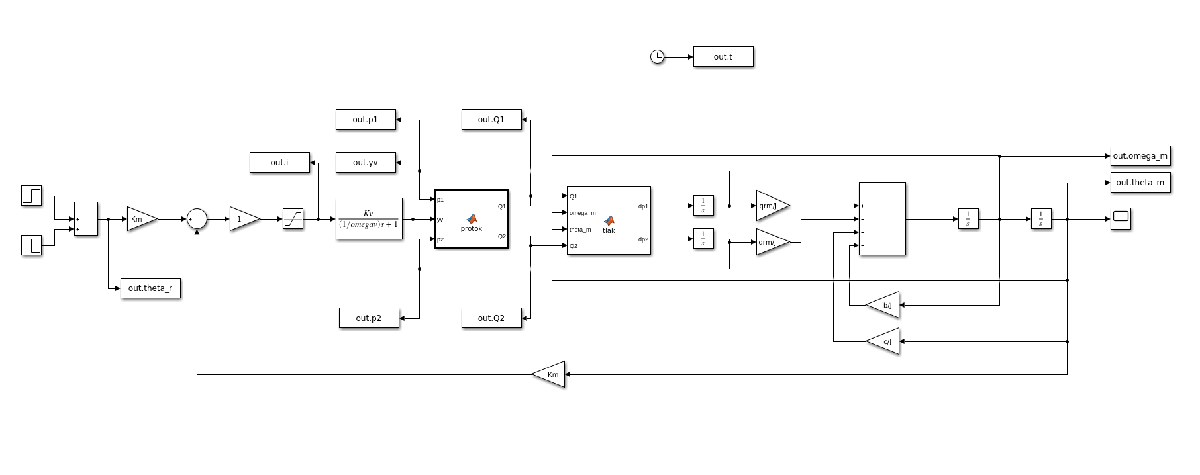

#### Matlab funkcija protok

#### Matlab funkcija tlak

### Simulacijski rezultati

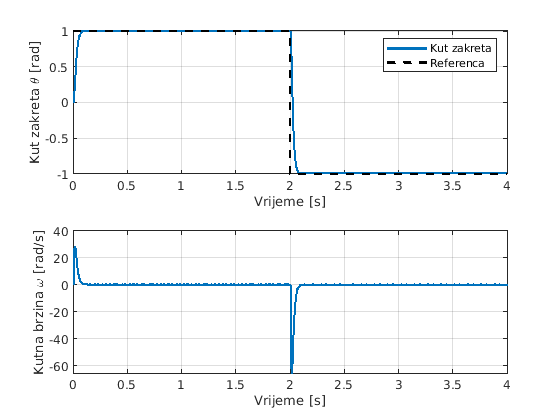

figure
subplot(2,1,1);
plot(out.t, out.theta_m, 'LineWidth', 2);
hold on
plot(out.t, out.theta_r, 'k--', 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kut zakreta \theta [rad]');
legend('Kut zakreta', 'Referenca');

subplot(2,1,2);
plot(out.t, out.omega_m, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kutna brzina \omega [rad/s]');

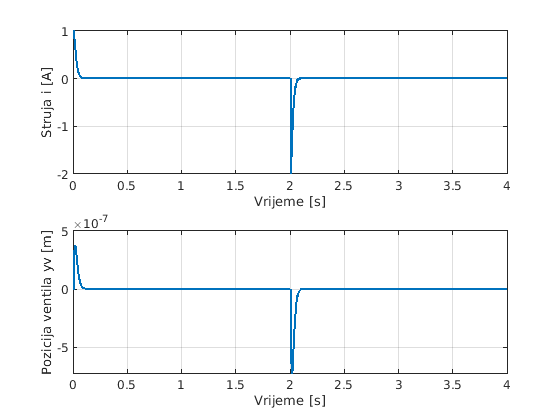

%plot 2
figure
subplot(2,1,1);
plot(out.t, out.i, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Struja i [A]');

subplot(2,1,2);
plot(out.t, out.yv, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Pozicija ventila yv [m]');

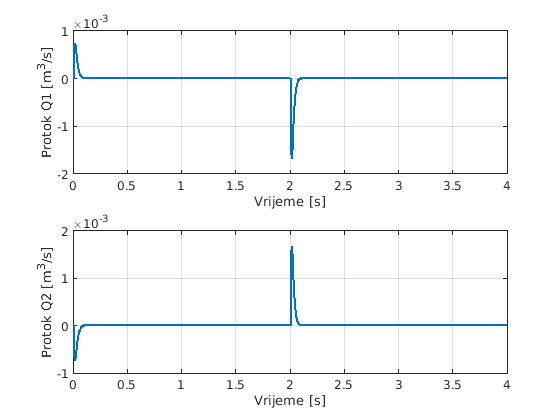

%plot 3
figure
subplot(2,1,1);
plot(out.t, out.Q1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q1 [m^3/s]');

subplot(2,1,2);
plot(out.t, out.Q2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q2 [m^3/s]');

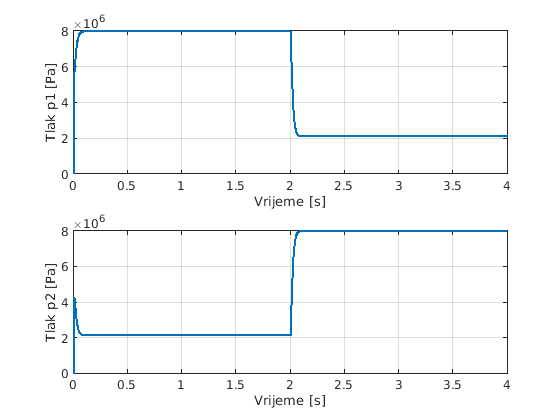

%plot 4
figure
subplot(2,1,1);
plot(out.t, out.p1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p1 [Pa]');

subplot(2,1,2);
plot(out.t, out.p2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p2 [Pa]');